# Sinus Approximation

### Beschreibung des Algorithmuses


$$k_1 * \phi - sgn(\phi) * k_2 * \phi^2$$


- [Quelle](http://www.mclimatiano.com/faster-sine-approximation-using-quadratic-curve/)

k1 = 1.27323954;
k2 = 0.405284735;
syms k3

### Inline version

% k1 * phi - sign(phi) .* k2 .* phi.^2

### Genauigkeit der Sinus Approximation

plot setup

phi= linspace(-pi,pi,101);
tiledlayout('flow'); nexttile;

line(phi,sin(phi),'Color','g')
line(phi, sineApprox(phi),'Color','r')
legend('sin(\phi)','sineApprox(\phi)','Location','best'); xlabel('\phi'); grid on; grid minor;

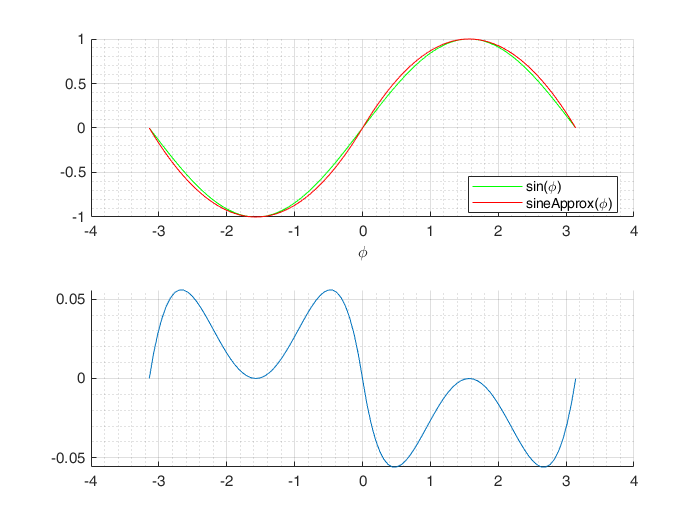

nexttile; grid on; grid minor;
line(phi,sin(phi)-sineApprox(phi))